# Lecture 7 Application of Matlab in Numerical Analysis I: Randomness

In matlab, random numbers are indeed *pseudorandom, *generated from [random number stream ](https://www.mathworks.com/help/matlab/ref/randstream.html)-- a series of numbers calculated by deterministic algorithms (e.g. numer theory). In principle, they do not satisfy the rigorous independent and identically distributed (i.i.d.) condition in probability theory, however they can pass  statistical tests on their distribution and correlation to show that they are good approximations -- that's typically sufficient for application purpose. 

rand % random number from uniform distribution (continuous)

ans = 0.4588

randn %random number from normal distribution

ans = -0.4442

randi([0 10]) % random integer from uniform distribution

ans = 3

## Example 1: Calculating $\pi$ with [Monte-Carlo Method](https://en.wikipedia.org/wiki/Monte_Carlo_method#History)

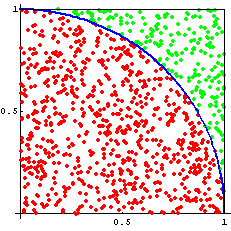

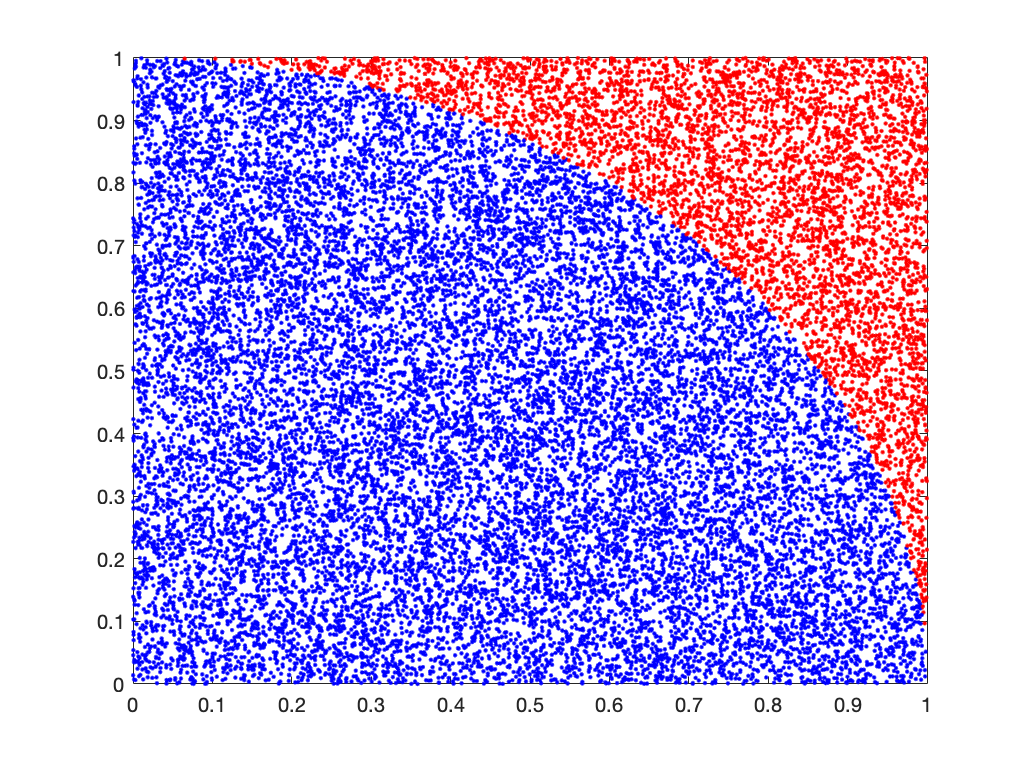

N = 9000;
x = rand(N,1);
y = rand(N,1);
r = x.^2+y.^2;
% get logicals 
inside = r<=1 ;
outside = r>1 ; % or simply outside = ~inside
% plot 
plot(x(inside),y(inside),'b.');
hold on  % continue plot within the same figure
plot(x(outside),y(outside),'r.');
hold off % stop the hold, creating new figure if N is changed

% get pi value 
pi_est = 4*sum(inside)/N  

pi_est = 3.1284

**Exercise:** Use the for-loop and if statements to implement the same algorithm

## **Example 2: Simulation of **[Random Walk](https://en.wikipedia.org/wiki/Random_walk#cite_note-6)

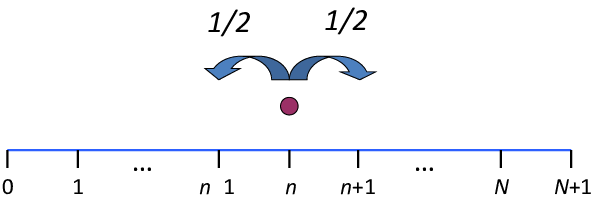

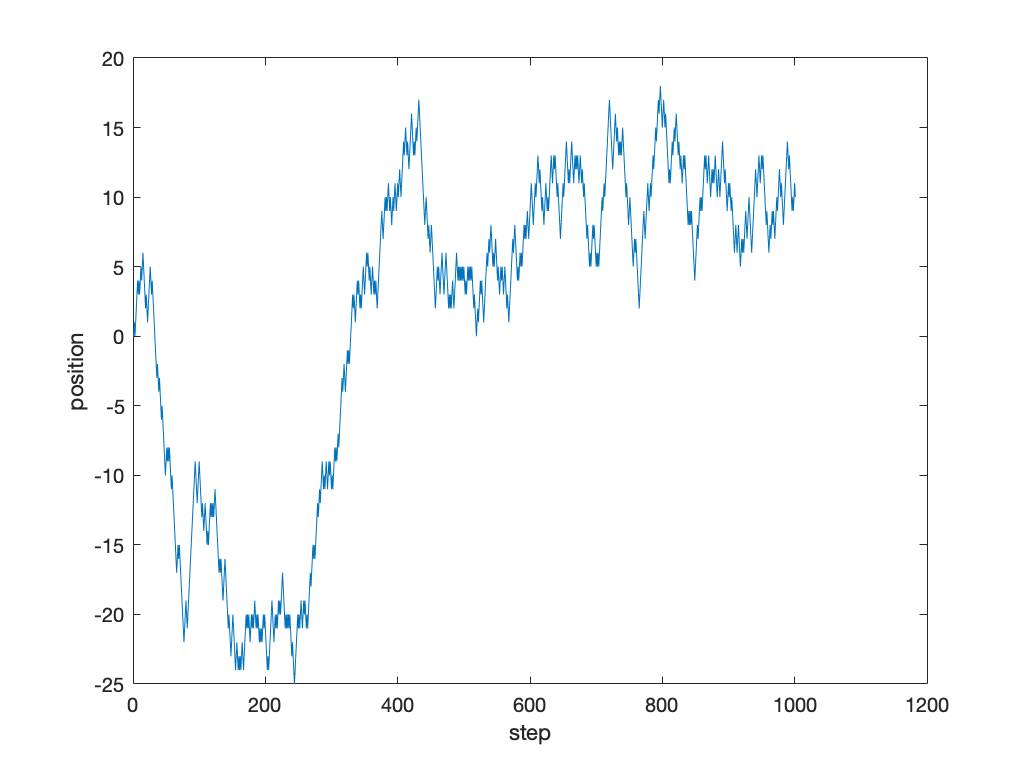

n = 1000;
v = random_walk(n);
plot(v)
xlabel('step')
ylabel('position')

Where is the random walker after n steps? It is a random number, but we can see its distribution with the histogram by simulating the random walk for N times.

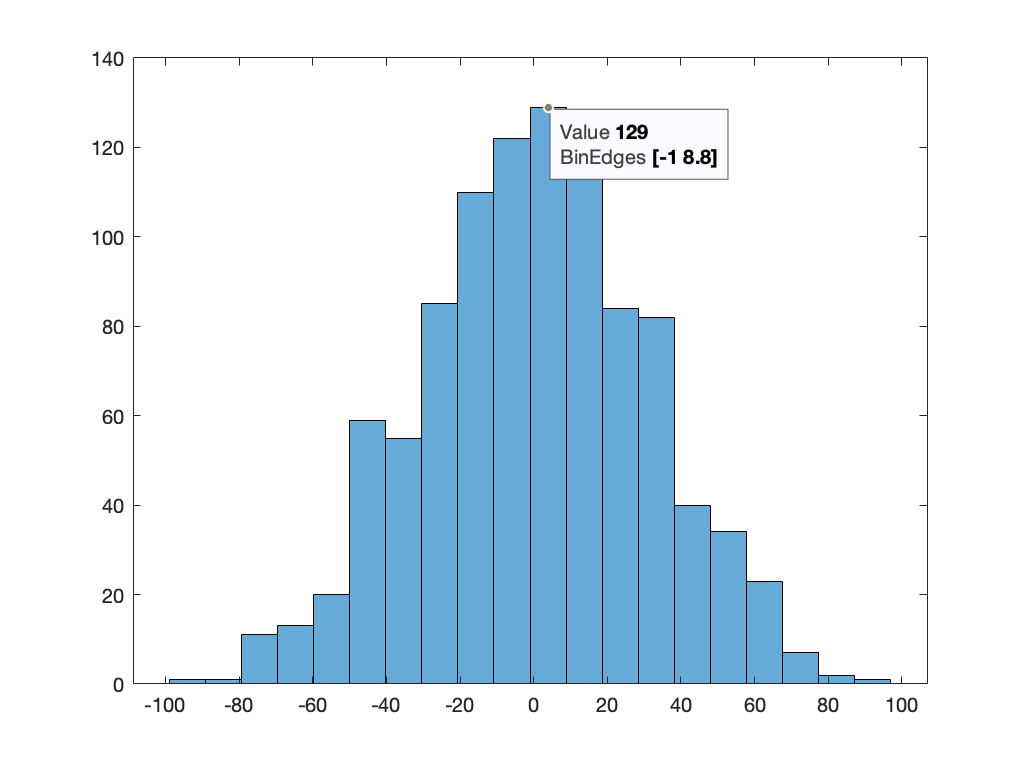

N = 1000;
pos_end = zeros(1,N);
for i = 1:N
    v = random_walk(n);
    pos_end(i) = v(end);
end
histogram(pos_end, 20) % the second value represent number of bins in histogram

**Exercise:**  How far on average will the random walker travel after n steps (i.e. the absolute value of the position after n steps)? Write the function `aver_dist(n,N) `to approximate this with N simulations

function v = random_walk(n)
% random walk of n steps, output the vector of length (n+1), whose first
% value is the initial position zero
    v = zeros(1,n+1); %first value stores the initial position
    for i = 2:n+1
        v(i) = v(i-1)+(-1)^randi(2);
    end
end